hum = [20 30 40 50].';
sampleRegion =[1:100].';
sampleOnes = ones(100, 1);
sampleX = procX(sampleRegion);

newX =    -6.8000
   -6.6000
   -6.4000
   -6.2000
   -6.0000
   -5.8000
   -5.6000
   -5.4000
   -5.2000
   -5.0000


sampleAL = [sampleOnes, sampleX];
sampleAQ = [sampleOnes, sampleX, sampleX.^2];
sampleAC = [sampleOnes, sampleX, sampleX.^2, sampleX.^3];

eCond = [8 20 28 34].';
onesV = ones(4, 1);

xVal = procX(hum);

newX =     -3
    -1
     1
     3


aLin = [onesV, xVal];
aQuad = [onesV, xVal, xVal.^2];
aCube = [onesV, xVal, xVal.^2, xVal.^3];

lsA = aLin.'*aLin; %Least squares matrix A and vector B
lsB = aLin.'*eCond;
x = mldivide(lsA, lsB);
xquad = mldivide(aQuad.'*aQuad, aQuad.'*eCond);
xcube = mldivide(aCube.'*aCube, aCube.'*eCond);

projectedOut = sampleAL*x;
quadProj = sampleAQ*xquad;
cubeProj = sampleAC*xcube;
title('Fitted Model')
xlabel('Coded Humidity')
ylabel('Electrical Conductivity')
hold on 
alt = aLin*x

alt =     9.6000
   18.2000
   26.8000
   35.4000


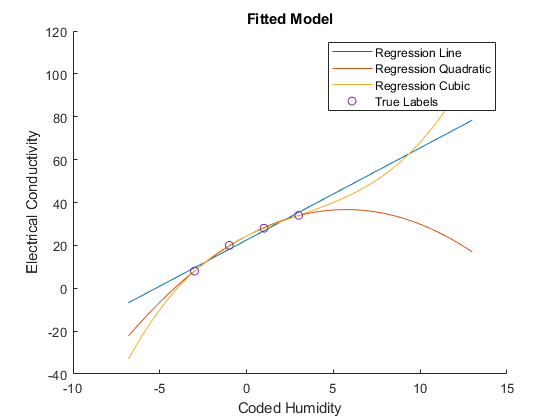

plot(sampleX, projectedOut)
plot(sampleX, quadProj)
plot(sampleX, cubeProj)
scatter(xVal, eCond)
legend('Regression Line', 'Regression Quadratic', 'Regression Cubic','True Labels')

function newX = procX(h)
    newX = (h-35)/5
end